## Segmentation using FCM with Bias Field Correction

**Author:** Harshit Varma

clear variables;
clc;

Load the data

DATA_PATH = "../data/data.mat";
data = load(DATA_PATH, "-mat");
img  = data.imageData;
mask = data.imageMask;

Display the data and save as JPG for easier access:

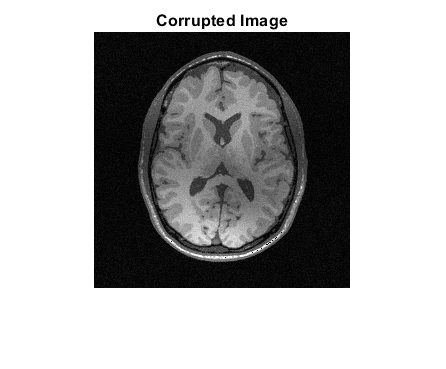

imshow(img); 
title("Corrupted Image");
saveas(gcf, "../plots/corrupted.jpg", "jpg");

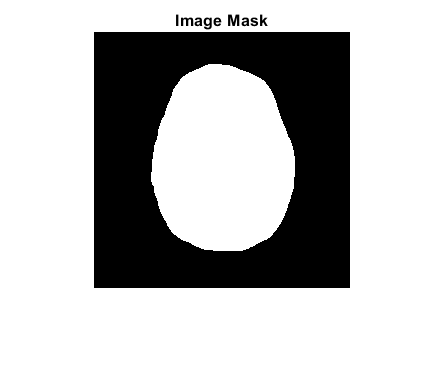


% We only need to segment inside the brain, the background-foreground
% segmentation is already provided by the mask
imshow(mask);
title("Image Mask");
saveas(gcf, "../plots/mask.jpg", "jpg");

[R, C] = size(img);

% Get the background (bg) and the foreground (fg) masks
mask_fg = (mask == 1);
mask_bg = (mask == 0);

Set the background values to 0 since we don't need them

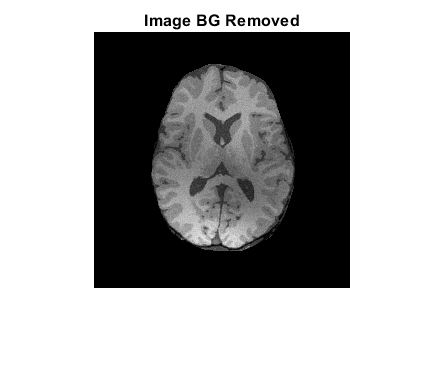

img(mask_bg) = 0;
imshow(img);
title("Image BG Removed");

### Initializing Bias, Class Means, Weights and Memberships

Setting the constant bias field to 1 yields the best results, this parameter affects the final estimates by a lot. A low value (say, 0.5) leads to very poor results.

Larger q leads to many more small artifacts in the bias-removed image. Lesser q leads to a less sharper/distinct bias-removed image

K = 3; % The number of categories for the segmentation (gray matter, white matter and CSF)
q = 5; % Must be chosen to be > 1.5

% Initial estimate for the bias is a constant image
b_const = 1;
b_init = (b_const .* ones(R, C)) .* mask;

sigma_kernel affects the final estimates by a lot. A low value leads to very noisy/un-smooth memberships and bias field.

% Initialize the fxf Gaussian Kernel
f = 9; 
sigma_kernel = 2.5;
w = fspecial("gaussian", f, sigma_kernel);

fprintf("The neighbourhood mask shown as an image:\n");

The neighbourhood mask shown as an image:


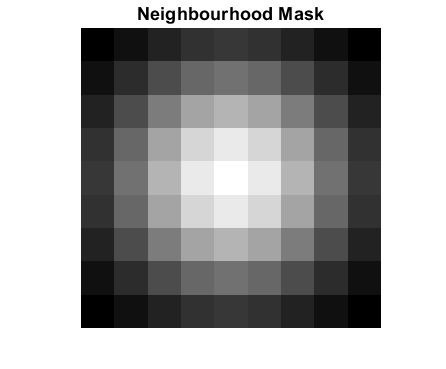

imshow(w, [], "InitialMagnification", "fit");
title("Neighbourhood Mask");
saveas(gcf, "../plots/neighbourhood_mask.jpg", "jpg");

We initialize the class means the memberships using the standard K-Means algorithm. The initial memberships are hard memberships assigned using the class means returned by K-Means.  

% Using K-Means to initialize the memberships and the class means
eps = 1e-7;
[seg_init, c_init, sigma_init] = KMeans(img, mask, K, eps);

K-Means ran for 17 iterations


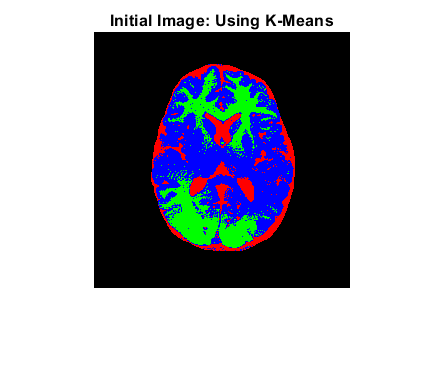


% Show and save the initial segmented image 
showSegmented(seg_init, K, "Initial Image: Using K-Means", "../plots/segment_kmeans.jpg");

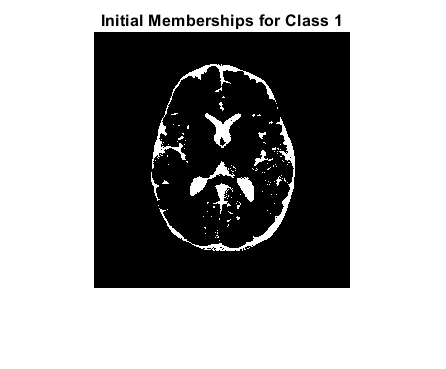

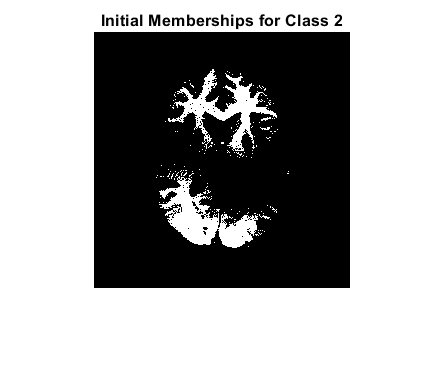

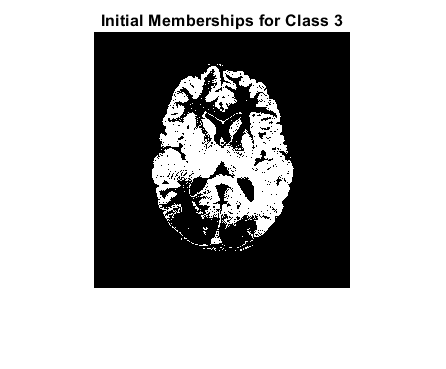

% Initializing memberships
u_init = zeros(R, C, K);
for k = 1:K
    mask_k = (seg_init == k);
    m = mask_k .* seg_init;
    u_init(:, :, k) = m;
    figure();
    imshow(m);
    title(sprintf("Initial Memberships for Class %d", k));
    saveas(gcf, sprintf("../plots/init_memberships_%d", k), "jpg");
end

% Initial Objective Function
J_init = objectiveFunction(img, b_init, c_init, q, u_init, w);

### The Algorithm

eps = 1e-5;
N_max = 200;

fprintf("Starting the Optimization:\n");

Starting the Optimization:


[u, b, c, J] = iterate(img, mask, u_init, b_init, c_init, q, w, J_init, eps, N_max);

Before: 12449.480469 | After: 56.815121
Iteration 1 completed

Before: 56.815121 | After: 52.912628
Iteration 2 completed

Before: 52.912628 | After: 50.236568
Iteration 3 completed

Before: 50.236568 | After: 48.024349
Iteration 4 completed

Before: 48.024349 | After: 46.126049
Iteration 5 completed

Before: 46.126049 | After: 44.501450
Iteration 6 completed

Before: 44.501450 | After: 43.209400
Iteration 7 completed

Before: 43.209400 | After: 42.302898
Iteration 8 completed

Before: 42.302898 | After: 41.668499
Iteration 9 completed

Before: 41.668499 | After: 41.161942
Iteration 10 completed

Before: 41.161942 | After: 40.729271
Iteration 11 completed

Before: 40.729271 | After: 40.387119
Iteration 12 completed

Before: 40.387119 | After: 40.115849
Iteration 13 completed

Before: 40.115849 | After: 39.885368
Iteration 14 completed

Before: 39.885368 | After: 39.711689
Iteration 15 completed

Before: 39.711689 | After: 39.566090
Iteration 16 completed

Before: 39.566090 | After: 39.

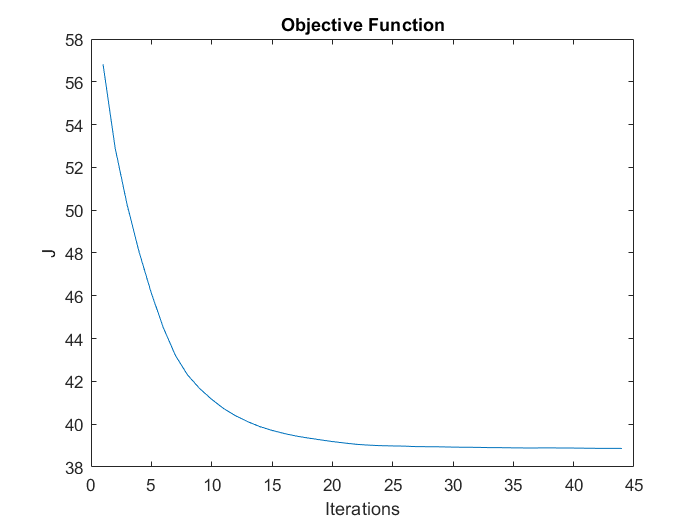

% Plot Objective Function
J = J(J ~= 0);
figure();
plot(1:length(J), J);
title("Objective Function");
ylabel("J");
xlabel("Iterations");
saveas(gcf, "../plots/objective_function.jpg", "jpg");

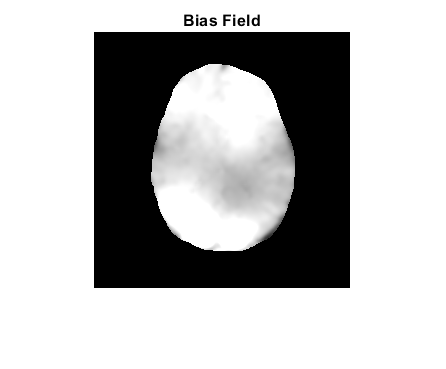

% Plot Bias Field
figure();
imshow(b);
title("Bias Field");
saveas(gcf, "../plots/bias_field.jpg", "jpg");

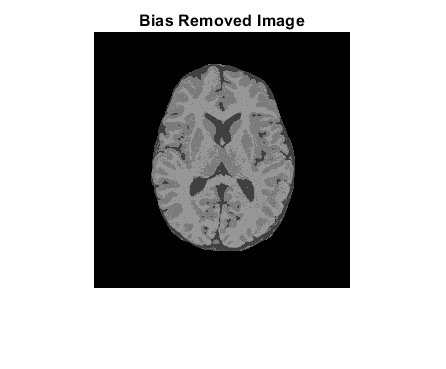

% Plot Bias-Removed Image
A = computeA(u, c);
figure();
imshow(A);
title("Bias Removed Image");
saveas(gcf, "../plots/bias_removed.jpg", "jpg");

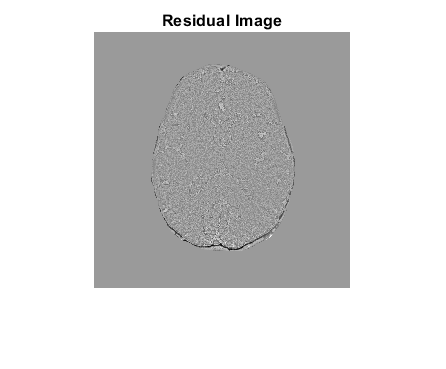

% Plot Residual Image
R = img - (A .* b);
figure();
imshow(R, []); % [] shows the detail, else it appears black
title("Residual Image");
saveas(gcf, "../plots/residual.jpg", "jpg");

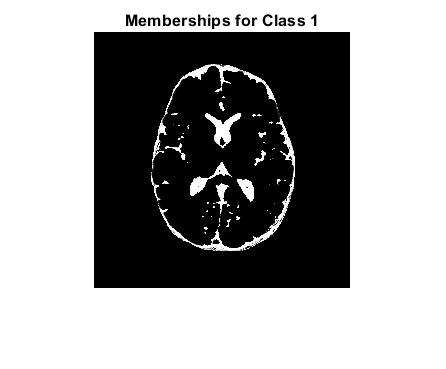

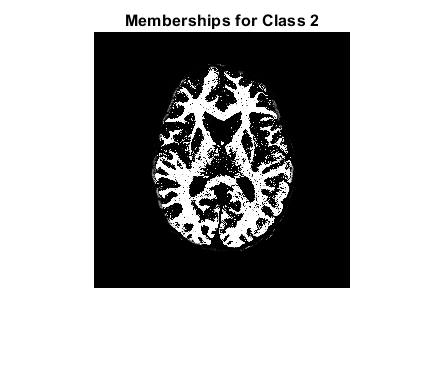

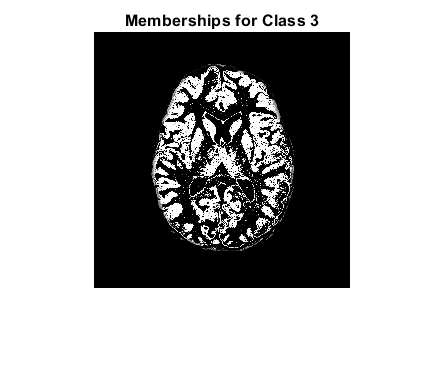

% Display memberships
for k = 1:K
    m = u(:, :, k);
    figure();
    imshow(m);
    title(sprintf("Memberships for Class %d", k));
    saveas(gcf, sprintf("../plots/memberships_%d.jpg", k), "jpg");
end